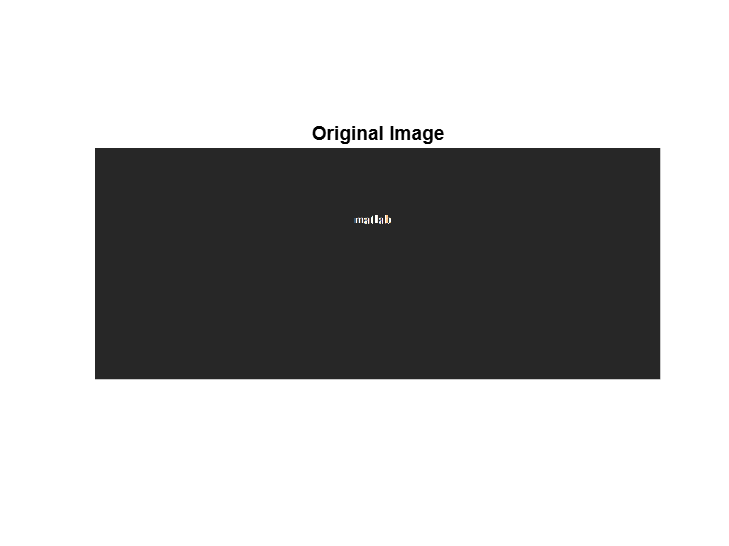

% Clear previous data and set up the environment
clc; clear; close all;

% Step 1: Load the Image
img = imread('Screenshot.png');  
figure, imshow(img);
title('Original Image');

disp('Step 1: Image loaded.');

Step 1: Image loaded.


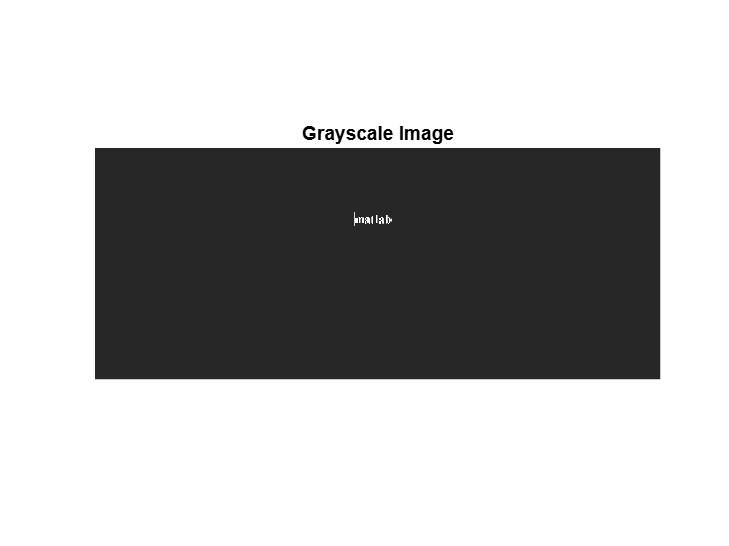


% Step 2: Convert to Grayscale
grayImage = rgb2gray(img);
figure, imshow(grayImage);
title('Grayscale Image');

disp('Step 2: Image converted to grayscale.');

Step 2: Image converted to grayscale.


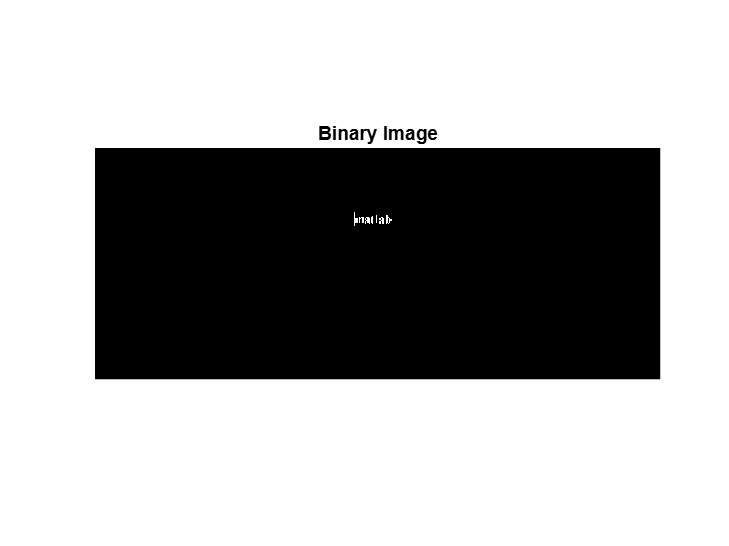


% Step 3: Binarize the Image (Thresholding)
binaryImage = imbinarize(grayImage);
figure, imshow(binaryImage);
title('Binary Image');

disp('Step 3: Image binarized.');

Step 3: Image binarized.


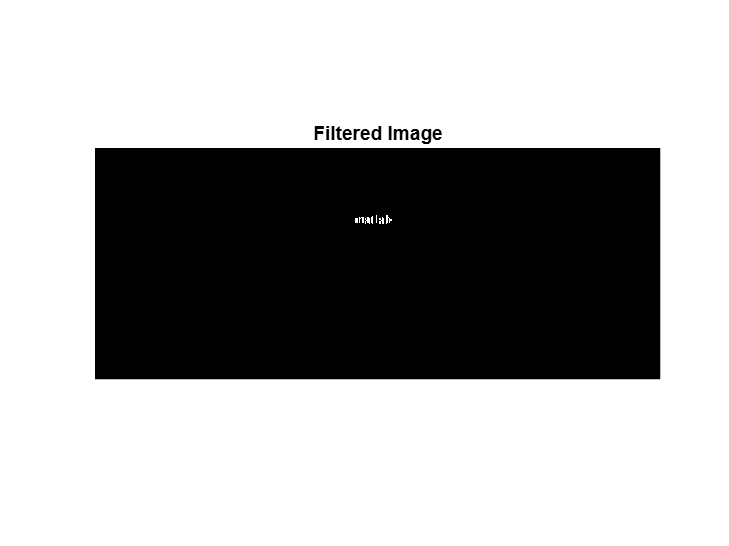


% Step 4: Noise Reduction 
% Apply median filtering to remove noise
filteredImage = medfilt2(binaryImage, [3 3]);
figure, imshow(filteredImage);
title('Filtered Image');

disp('Step 4: Noise reduction applied with median filtering.');

Step 4: Noise reduction applied with median filtering.


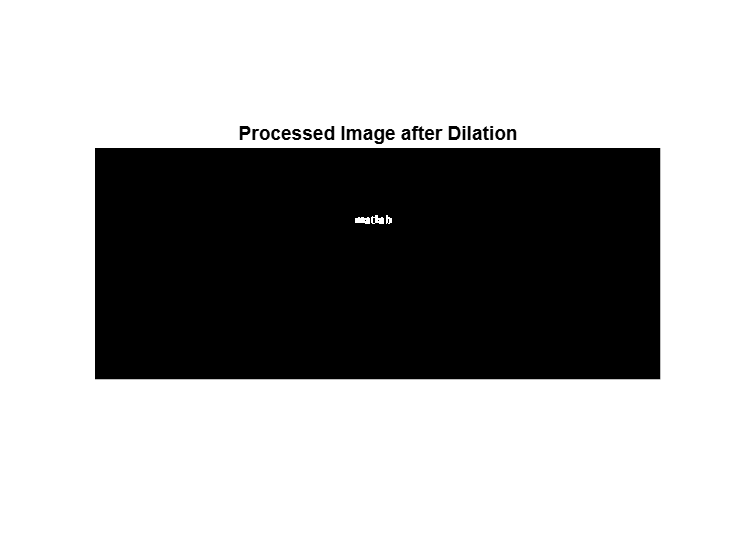


% Step 5: Morphological Processing
% Dilation to connect characters in the image
se = strel('line', 5, 0); 
processedImage = imdilate(filteredImage, se);
figure, imshow(processedImage);
title('Processed Image after Dilation');

disp('Step 5: Morphological processing applied (dilation).');

Step 5: Morphological processing applied (dilation).


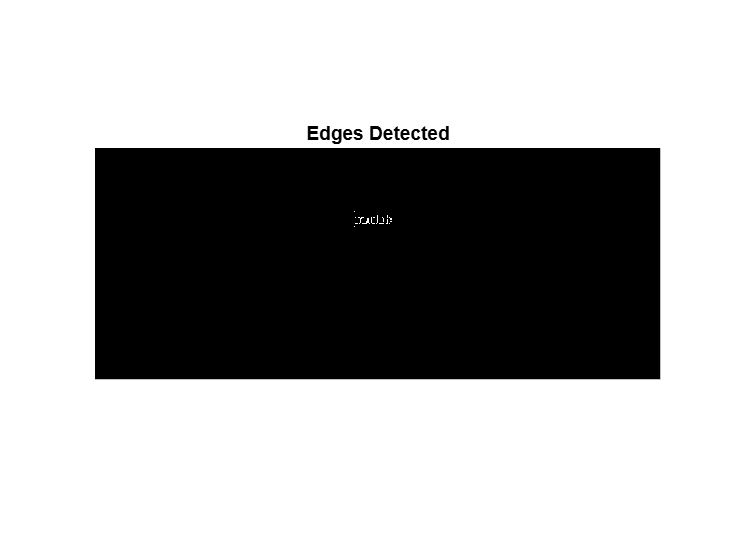


% Step 6: Text Region Detection 
% Use edge detection to find text boundaries
edges = edge(grayImage, 'Canny');
figure, imshow(edges);
title('Edges Detected');

disp('Step 6: Edge detection completed.');

Step 6: Edge detection completed.


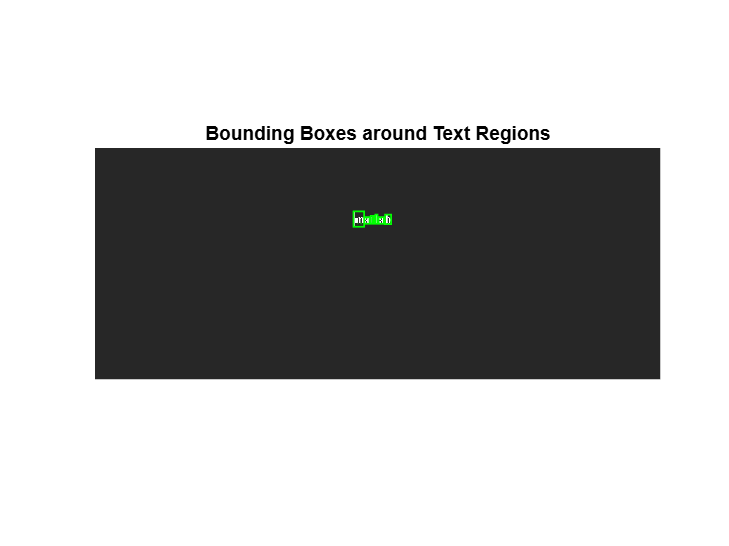


% Find connected components and bounding boxes around potential text
stats = regionprops(edges, 'BoundingBox');
figure, imshow(grayImage);
hold on;
for i = 1:length(stats)
    rectangle('Position', stats(i).BoundingBox, 'EdgeColor', 'g', 'LineWidth', 1);
end
hold off;
title('Bounding Boxes around Text Regions');

disp('Step 6: Bounding boxes drawn around detected text regions.');

Step 6: Bounding boxes drawn around detected text regions.



% Step 7: Perform OCR
% OCR on the Entire Image
results = ocr(processedImage);  
recognizedText = results.Text;
disp('Step 7: OCR performed on the entire image.');

Step 7: OCR performed on the entire image.


disp('Recognized Text from Entire Image:');

Recognized Text from Entire Image:


disp(recognizedText);

matlab





disp('OCR process completed.');

OCR process completed.
